CSCE 5222: Feature Engineering

Group Project

Extracting line features for boundary detection

Data Collection 

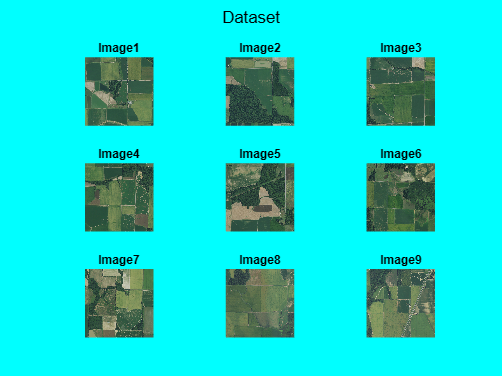

image_dataset = readImages('data/dataset');
showImages(image_dataset, 'Dataset', 'Image');

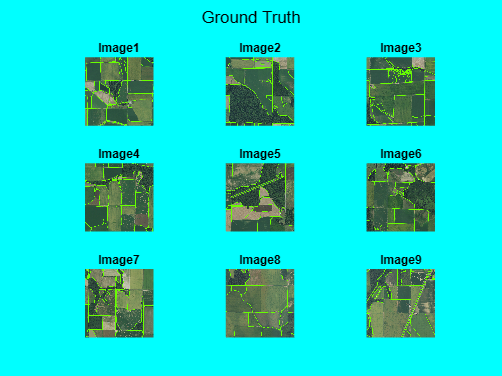


ground_truth_image = readImages('data/ground_truth');
showImages(ground_truth_image, 'Ground Truth', 'Image');

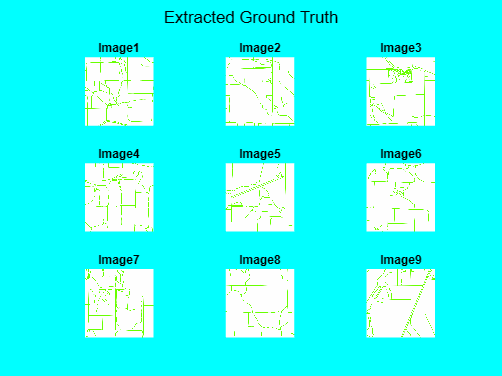


extracted_ground_truth_image = readImages('data/extracted_ground_truth');
showImages(extracted_ground_truth_image, 'Extracted Ground Truth', 'Image');

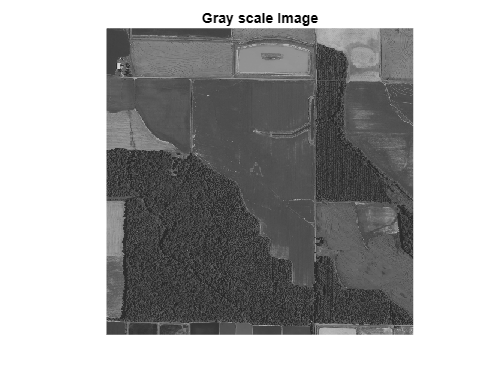

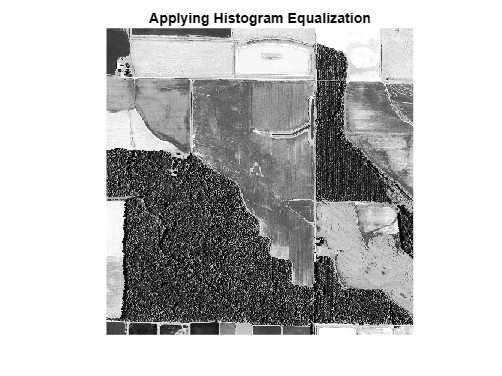

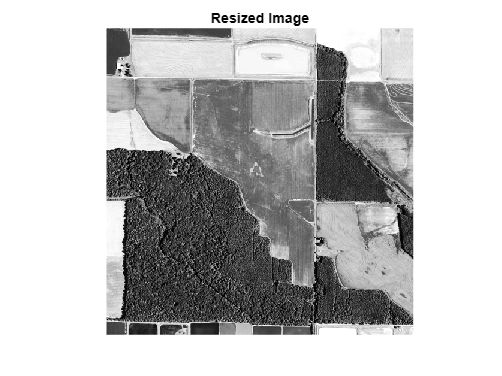

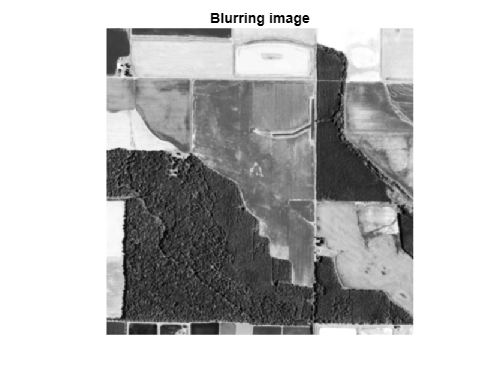

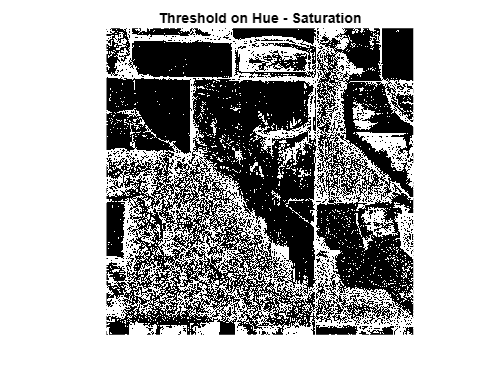

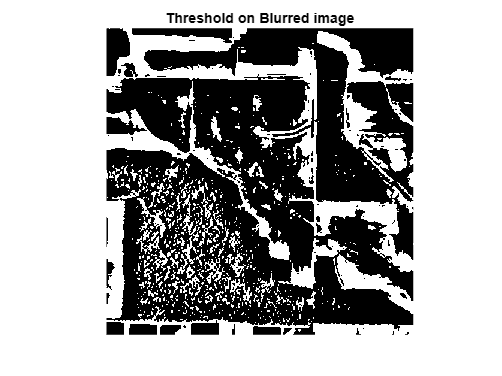

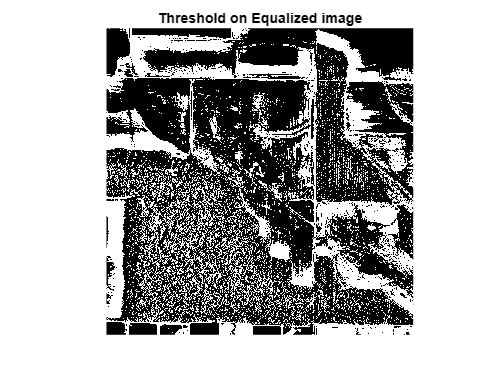

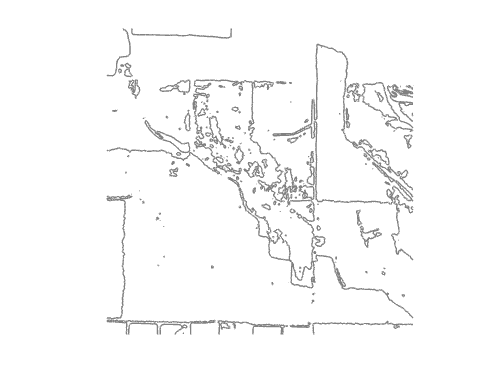

image = image_dataset{2};
ground_truth = ground_truth_image{2};

boundary_detection(image, ground_truth_image);

Main

function boundary_detection(image, ground_truth)

    % Convert image into grayscale
    gray_image = im2gray(image);
    showImage(gray_image, 'Gray scale Image');

    % Equalize image for better contrast
    equalized_image = histeq(gray_image);
    showImage(equalized_image, 'Applying Histogram Equalization');

    % Resize to get only important features for edges
    resized_image = resizeImage(equalized_image, 0.25);
    showImage(resized_image, 'Resized Image');

    % Blur to reduce noise
    blur_image = blurImage(resized_image, 1);
    showImage(blur_image, 'Blurring image');

    [H, S, V] = rgb2hsv(image);

    % Apply threshold on H-S
    threshold_image_h_s = apply_adaptive_threshold(H-S, 0.5);
    showImage(threshold_image_h_s, 'Threshold on Hue - Saturation');
    
    % Apply threshold
    threshold_image_blur = apply_adaptive_threshold(blur_image, 0.5);
    showImage(threshold_image_blur, 'Threshold on Blurred image');

    % Apply threshold equalized
    threshold_image_equalized = apply_adaptive_threshold(equalized_image, 0.5);
    showImage(threshold_image_equalized, 'Threshold on Equalized image');

    % Contour
    draw_contour(blur_image, 1);
    contour = save_current_figure_and_return('results/images/processing/contout_h_s.png');
    showImage(contour, 'Contour oh H-S');

    % equalize
    contour_equalize = histeq(im2gray(contour));
    showImage(contour_equalize, 'Contour Equalize');


    contour_equalize = histeq(contour_equalize);
    showImage(contour_equalize, 'Contour Equalize');

    % blur
    contour_blur = blurImage(contour, 2);

    % Apply threshold equalized
    contour_threshold = apply_adaptive_threshold(contour_blur, 0.5);
    showImage(contour_threshold, 'Threshold on Contour of image');

    % resize
    contour_resize = imresize(contour_blur, 0.4);
    showImage(contour_resize, 'Contour Resize 0.25');

    % Apply threshold equalized
    contour_threshold = apply_adaptive_threshold(contour_resize, 0.7);
    showImage(contour_threshold, 'Threshold on Contour of image');

    % resize
    t_h_s = imresize(threshold_image_h_s, 0.25);

    % blur
    t_h_s = blurImage(uint8(t_h_s)*255, 2);

    % Blur to reduce noise

    % Edge detection
    edgeImage = detect_edges(im2gray(contour_resize), 'sobel');
    showImage(edgeImage, ' Sobel Edge Detection ');

    detectEdges(edgeImage);

    % Hough Transform
    detectedLines = houghTransformLines(edgeImage, 1);

    % Visualize the detected lines 
    figure, imshow(edgeImage), hold on; 
    for k = 1:length(detectedLines)
        xy = [detectedLines(k).point1; detectedLines(k).point2]; 
        plot(xy(:, 1), xy(:, 2), 'LineWidth', 1, 'Color', 'green'); 
    end
    % title(['Resize: ', num2str(resizeFactor), ', Filter: ', char(filterType), ', Blur: ', num2str(blurLevel)]);
    hold off;

    visualizeHoughTransform(edgeImage, detectedLines);

    % Plot the result on plain background

    % Binarize image and ground truth

    % Performance measure
    
end

Pre-processing

function blur_image = blurImage(image, blurLevel)
    blur_image = imgaussfilt(image, blurLevel);
end

function resized_image = resizeImage(image, resizeMeasure)
    resized_image = imresize(image, resizeMeasure);
end

function binaryImage = apply_adaptive_threshold(image, sensitivity)
    image = im2gray(image);
    binaryImage = imbinarize(image, 'adaptive', 'Sensitivity', sensitivity);
end

function [H, S, V] = get_HSV(image)
    [H, S, V] = rgb2hsv(cat(3, image, image, image));
end

Image processing

function edgeImage = detect_edges(image, filterType)
    edgeImage = edge(image, char(filterType));
end

function draw_contour(image, level)

    white_background = ones(size(image))*256;
    imwrite(white_background, 'white.png');
    white = imread('white.png');
    
    figure;
    % Create a set of axes
    ax = axes();
    % Display the white background image in the axes
    I = imshow(white, 'Parent', ax);
    % Overlay contours on the white background
    hold on;
    contour(ax, image, level); % You can specify the line color as 'black' or any other color
    hold off;
end

function image = save_current_figure_and_return(image_path)
    saveas(gcf(), image_path);
    image = imread(image_path);
end

Hough Transform Line Detection

function lines = houghTransformLines(image, minLength)
    if size(image, 3) == 3
        image_gray = rgb2gray(image);
    else
        image_gray = image;
    end
 
    edges = edge(image_gray, 'canny');

    [H, T, R] = hough(edges);
    P = houghpeaks(H, 50, 'Threshold', ceil(0.3*max(H(:))));
    lines = houghlines(edges, T, R, P, 'FillGap', 5, 'MinLength', minLength);
end

function visualizeHoughTransform(image, detectedLines)
    figure, imshow(image), hold on; 
    for k = 1:length(detectedLines)
        xy = [detectedLines(k).point1; detectedLines(k).point2]; 
        plot(xy(:, 1), xy(:, 2), 'LineWidth', 2, 'Color', 'green'); 
    end
    % title(['Resize: ', num2str(resizeFactor), ', Filter: ', char(filterType), ', Blur: ', num2str(blurLevel)]);
    hold off;
end

Post Processing

Evaluation

Input/Output Operations

function images = readImages(folderPath)
    % Get a list of all image files in the specified folder
    imageFiles = dir(fullfile(folderPath, '*.png'));  % Change the extension based on the image format you have (e.g., '*.jpg', '*.jpeg', '*.bmp', etc.)

    % Initialize an empty cell array to store the images
    images = cell(1, numel(imageFiles));

    % Loop through each image file and read the image
    for i = 1:numel(imageFiles)
        % Construct the full file path
        imagePath = fullfile(folderPath, imageFiles(i).name);

        % Read the image
        img = imread(imagePath);

        % Store the image in the cell array
        images{i} = img;
    end
end

function showImages(imageArray, main_title, sub_title)
    % Check if the imageArray is not empty
    if isempty(imageArray)
        disp('Image array is empty.');
        return;
    end

    % Get the number of images
    numImages = numel(imageArray);

    % Calculate the number of rows and columns for the grid
    numRows = ceil(sqrt(numImages));
    numCols = ceil(numImages / numRows);

    % Create a single figure for all images
    figure('Color', 'cyan');  % Set the background color to black
    
    % Set a title
    sgtitle(main_title);

    % Loop through each image and display it in the grid
    for i = 1:numImages
        subplot(numRows, numCols, i);
        imshow(imageArray{i});
        title([sub_title, '', num2str(i)]);
    end

    
end

function showImage(image, fig_title)
    
    figure;
    imshow(image);
    title(fig_title);

end

Pre-processing

Processing

Edge Detection

Line detection

function detectEdges(edgeImage)

    % Convert to binary if needed
    if ~islogical(edgeImage)
      edgeImage = imbinarize(edgeImage);
    end

    % Choose a structuring element size based on desired path width (e.g., disk of radius 5)
    se = strel('disk', 1);
    
    % Dilate the edge image
    dilatedImage = imdilate(edgeImage, se);

    % Use bwlabel to label connected components in the dilated image
    [labeledImage, numObjects] = bwlabel(dilatedImage);
    
    % Visualize the labeled components (optional)
    figure; imshow(label2rgb(labeledImage));

    % Loop through labeled objects and extract properties like area, centroid
    for i = 1:numObjects
      % Get current object mask
      objectMask = labeledImage == i;
    
      % Calculate object properties (e.g., area, centroid)
      area = sum(objectMask(:));
      centroid = regionprops(objectMask, 'Centroid').Centroid;
    
      % Store or process object information as needed
    end




end

Post-processing

Evaluation

function jaccardIndex = calculateJaccardIndex(image, reference)
end

function SSIM = calculateStructureSimilarity(image, reference)
    SSIM = ssim(image, double(reference));
end

function accuracy = calculateAccuracy(image, reference)
end

function precision = calculatePrecision(image, reference)
end

function recall = calculateRecall(image, reference)
end